## Lab #3: Asking a statistical question

## Problem 1

In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.

To make this a bit concrete, we will simulate a little data. Start by simulating 100k 'good' data points assuming Gaussian fluctations.

In order simulating 100k 'good' data points assuming Gaussian fluctuations we need mean and stander deviation. In this case the mean will be 12 since the temperature data is mostly consistent with 12 Kelvin and the stander deviation will be 0.4 since the thermometry is 0.4-degree precision.

clear;clc;clf;

mu = 12;
sig = 0.4;

gauss = makedist("Normal", "mu", mu, "sigma", sig);
gooddata = random(gauss,1,100000);

adding the following 'bad' datapoints: {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7} to the good data.

baddata = [10. 10.3 2.1 0. 0. 15.6 22.3 12.7];
temps = [gooddata,baddata];
temps= sort(temps);

As show on the graph the data randomly generated is well fit under the Gaussian distribution curve with mean as 12 and stander deviation as 0.4.

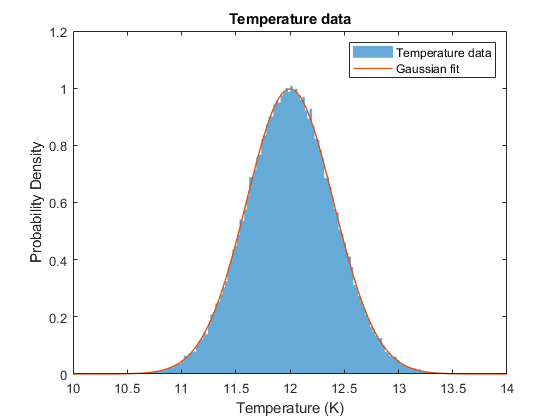


figure (1)
histogram(temps,1000,"Normalization","pdf",'EdgeColor',"none")
hold on
x2 = 10:0.01:14;
plot(x2,pdf(gauss,x2),"LineWidth",1);
legend('Temperature data', 'Gaussian fit');
xlabel('Temperature (K)')
ylabel('Probability Density')
title('Temperature data');
xlim([10 14])
hold off

The  statistical question

Since the main point for this part is to define the outliers in over all data. We will keep the data that is 5 sigma within form the mean. Can we find the outliers that exceed this 5 sigma of values? And is there as better value for X time sigma that keeps most of good data and removes most of bad data?

We start with finding the outliers that is 5 sigma away from the mean. Since standard deviation is the same as the sigma for Normal distribution. In order to find threshold of 5 sigma all we need is five times sigma. In this case we find some of the outliers. 

threshold = 5 * sig;
outliers = [temps(temps < (mu - threshold)) temps(temps > (mu + threshold))];
disp(outliers);

         0         0    2.1000   15.6000   22.3000



disp("the number of outliers that exceed 5 sigma is " + length(outliers));

the number of outliers that exceed 5 sigma is 5


Next, we try to find optimal value for X time sigma that keeps most of good data and removes most of bad data. One we I think we can do is try as much value as possible for X and find the maximum value of good data identified as being good and maximum value of bad data identified as being bad , and the minimum value of bad data identified as good and the minimum value of good data identified as bad. 

So, what I did is create a huge array of value of prefix for sigma. Then test each prefix to find it's True Pos (good data), True Neg (omission), False Neg (bad data), and False Pos (commission). Find the minimum number of the False Neg and False Pos occur, and maximum number of the True Pos and True Neg occur. Use the value we found to find the index of the prefix for sigma in the huge array. Pick out the prefix for sigma and find the outliers. Compare the outlier with the good data and bad data to find True Pos (good data), True Neg (omission), False Neg (bad data), and False Pos (commission). 

Since the method I used to find the best prefix for the sigma depend on the random number that I generated. The threshold I chose changes every time I run the lab. So, the number of omissions is not a predictable quantity. (some time it shows up as 1 or 2, but most time is 0)

There are mistakes of commission. They are not avoidable since some of the bad data was close to the range of plus or minus of 0.4 stander deviation. And the method I used is try keeps most of good data and removes most of bad data. Which means if the False Pos go to zero the Ture Neg would hugely go up. 

num_true_pos = [];
num_true_neg = [];
num_false_pos = [];
num_false_neg = [];

prefix = linspace(0, 10, 500);
for i = prefix
    
    outliers = [temps(temps < (mu - i * sig )) temps(temps > (mu + i * sig))];
    data_keeped = temps(~ismember(gooddata, outliers));
    
    true_pos = temps(ismember(data_keeped,gooddata));
    true_neg = temps(ismember(outliers, baddata));
    false_pos = temps(ismember(data_keeped, baddata));
    false_neg = temps(ismember(outliers, gooddata));
    
    num_true_pos = [num_true_pos, length(true_pos)];
    num_true_neg = [num_true_neg, length(true_neg)];
    num_false_pos = [num_false_pos, length(false_pos)];
    num_false_neg = [num_false_neg, length(false_neg)];
    
end

[~, index] = min(num_false_neg + num_false_pos);
best_prefix = prefix(index);
[~, index] = max(num_true_pos + num_true_neg);
best_prefix = prefix(index);
outliers = [temps(temps < (mu - best_prefix* sig)) temps(temps > (mu + best_prefix* sig))];
disp("the best prefix for sigma is " + best_prefix);

the best prefix for sigma is 4.7295


disp("number of outliers is " + length(outliers));

number of outliers is 6


disp(["outliers are"  string(outliers)]);

    "outliers are"    "0"    "0"    "2.1"    "10"    "15.6"    "22.3"



TP = length(temps(~ismember(gooddata, outliers))); %True Pos(good data)
FN = length(temps(ismember(baddata, outliers))); %False Neg(bad data)
TN = length(temps(ismember(gooddata, outliers))); %True Neg(omission)
FP = length(temps(~ismember(baddata, outliers))); %False Pos(commission)
disp(["True Pos " + TP , "False Neg " + FN, "False Pos " + FP, "True Neg " + TN]);

    "True Pos 100000"    "False Neg 6"    "False Pos 2"    "True Neg 0"



## Problem 2

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS. Or said another way, if I histogram how far all the (stationary) stars appear to have moved I get something like: 

If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?

We want to know the distance an object has to travel before we can consider it is an asteroid. In order to know the distance, we would like to ask:

What is the distance away from the origin might produce a significance position measurement in the 2D Gaussian with 1 arcsecond RMS? In this case the significance position measurement we want is 5 sigma away, and we want know what is the minimum threshold to have 5 sigma detected?

We are given the 2D standard normal distributions with mean 0 and sigma 1. So， our pdf are defined as $\mathrm{pdf}\left(x,y\right)=A\cdot e^{-\frac{1}{2}\left(x^2 +y^2 \right)}$ where A is a normalization coefficient. We can transfer this equation to polar coordinate since the only thing we care here is the distance away from the center. which is easier to solve in polar coordinates. in polar coordinates $r=\sqrt{\;x^2 +y^2 }$. The pdf became$\mathrm{pdf}\left(r\right)=A\cdot e^{-\frac{1}{2}\cdot r^2 }$. The normalization coefficient can be solved since the r is between 0 and infinity. So, we can set the integral of pdf equal to 1 and the range of the integral is 0 to infinity, $1=\int_0^{\infty } A\cdot e^{-\frac{1}{2}\cdot r^2 } \mathrm{dr}$. By using Gaussian integral table, we can find that this coefficient A is $\sqrt{\frac{2}{\pi \;}}$. Plug the coefficient A back into the pdf function we got  $\mathrm{pdf}\left(r\right)=\sqrt{\frac{2}{\pi \;}}\cdot e^{-\frac{1}{2}\cdot r^2 }$. We know the 5 sigma equal 1 in 3.5 million by the z-table. Now all we need to do is to integrate the pdf function from 0 to x and get 1 in 3.5 million solve for x,$\int_0^x \sqrt{\frac{2}{\pi \;}}\cdot e^{-\frac{1}{2}\cdot r^2 } \mathrm{dr}=\frac{1}{3\ldotp 5\cdot {10}^6 }$. The x will be the minimum distance the object has to travel for the object to be considered as asteroid.

## Problem 3

As we discussed in class, one of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).

Assume a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?

The question I like to ask is: When we observe the cosmic ray for 15 days, what is the probability that we observe 6800 cosmic rays or less base on the distribution of expected cosmic ray observations, cause by the moon blocking some of the rays form reaching the Earth?

We can assume that cosmic ray’s distribution over time forms a Poisson distribution with an average arrival rate equal to the numbers of the cosmic rays should arrived. We can assume it is Poisson distribution because the cosmic rays arrived independently and randomly in time. We normally have a cosmic ray rate of 1 cosmic ray per minute. We can observe where the moon is for 8 hours per night and we observe for 15 days. We get the average arrival rate $1\left(\mathrm{cosmic}\;\mathrm{ray}\;\mathrm{per}\;\mathrm{minute}\right)\cdot 60\left(\mathrm{minute}\;\mathrm{in}\;\mathrm{hour}\right)\cdot 8\left(\mathrm{hour}\;\mathrm{per}\;\mathrm{day}\right)\cdot 15\left(\mathrm{total}\;\mathrm{days}\right)=7200$. The average arrival rate in this case will be 7200. To solve for the probability, we need to perform a discrete sum of the Poisson pdf from 0 to 6800. $P\left(k\le 6800\right)=\sum_{k=0}^{6800} \lambda^k \frac{e^{-\lambda } }{k!}$

$\lambda$, `lambda,` will be the average arrival rate 7200.

clear;clc;clf;
pb = poisscdf(6800, 7200);
disp("The probability is " + pb);

The probability is 1.0133e-06


The probability that we would observe 6800 cosmic rays or less from a Poisson distribution is very small. It is on the order of ${10}^{-6}$.

sig = abs(norminv(pb));
disp("The probability is " + sig);

The probability is 4.7507


Since the sigma we get is less than 5 sigma, which most we will not consider it as a significant discovery in the physic application.